# Step 2: 制御器

発電機などの機器に付けるローカル制御器（AVR・PSS・ガバナなど）と、系統に付けるグローバル制御器（AGC）の選び方と付け外しの方法をまとめます。系統の組み立て方と、機器の追加・置き換え・取り外しは Step 1 で扱いました。

この Step は、GUILDA の基本的な流れの赤枠の部分です。

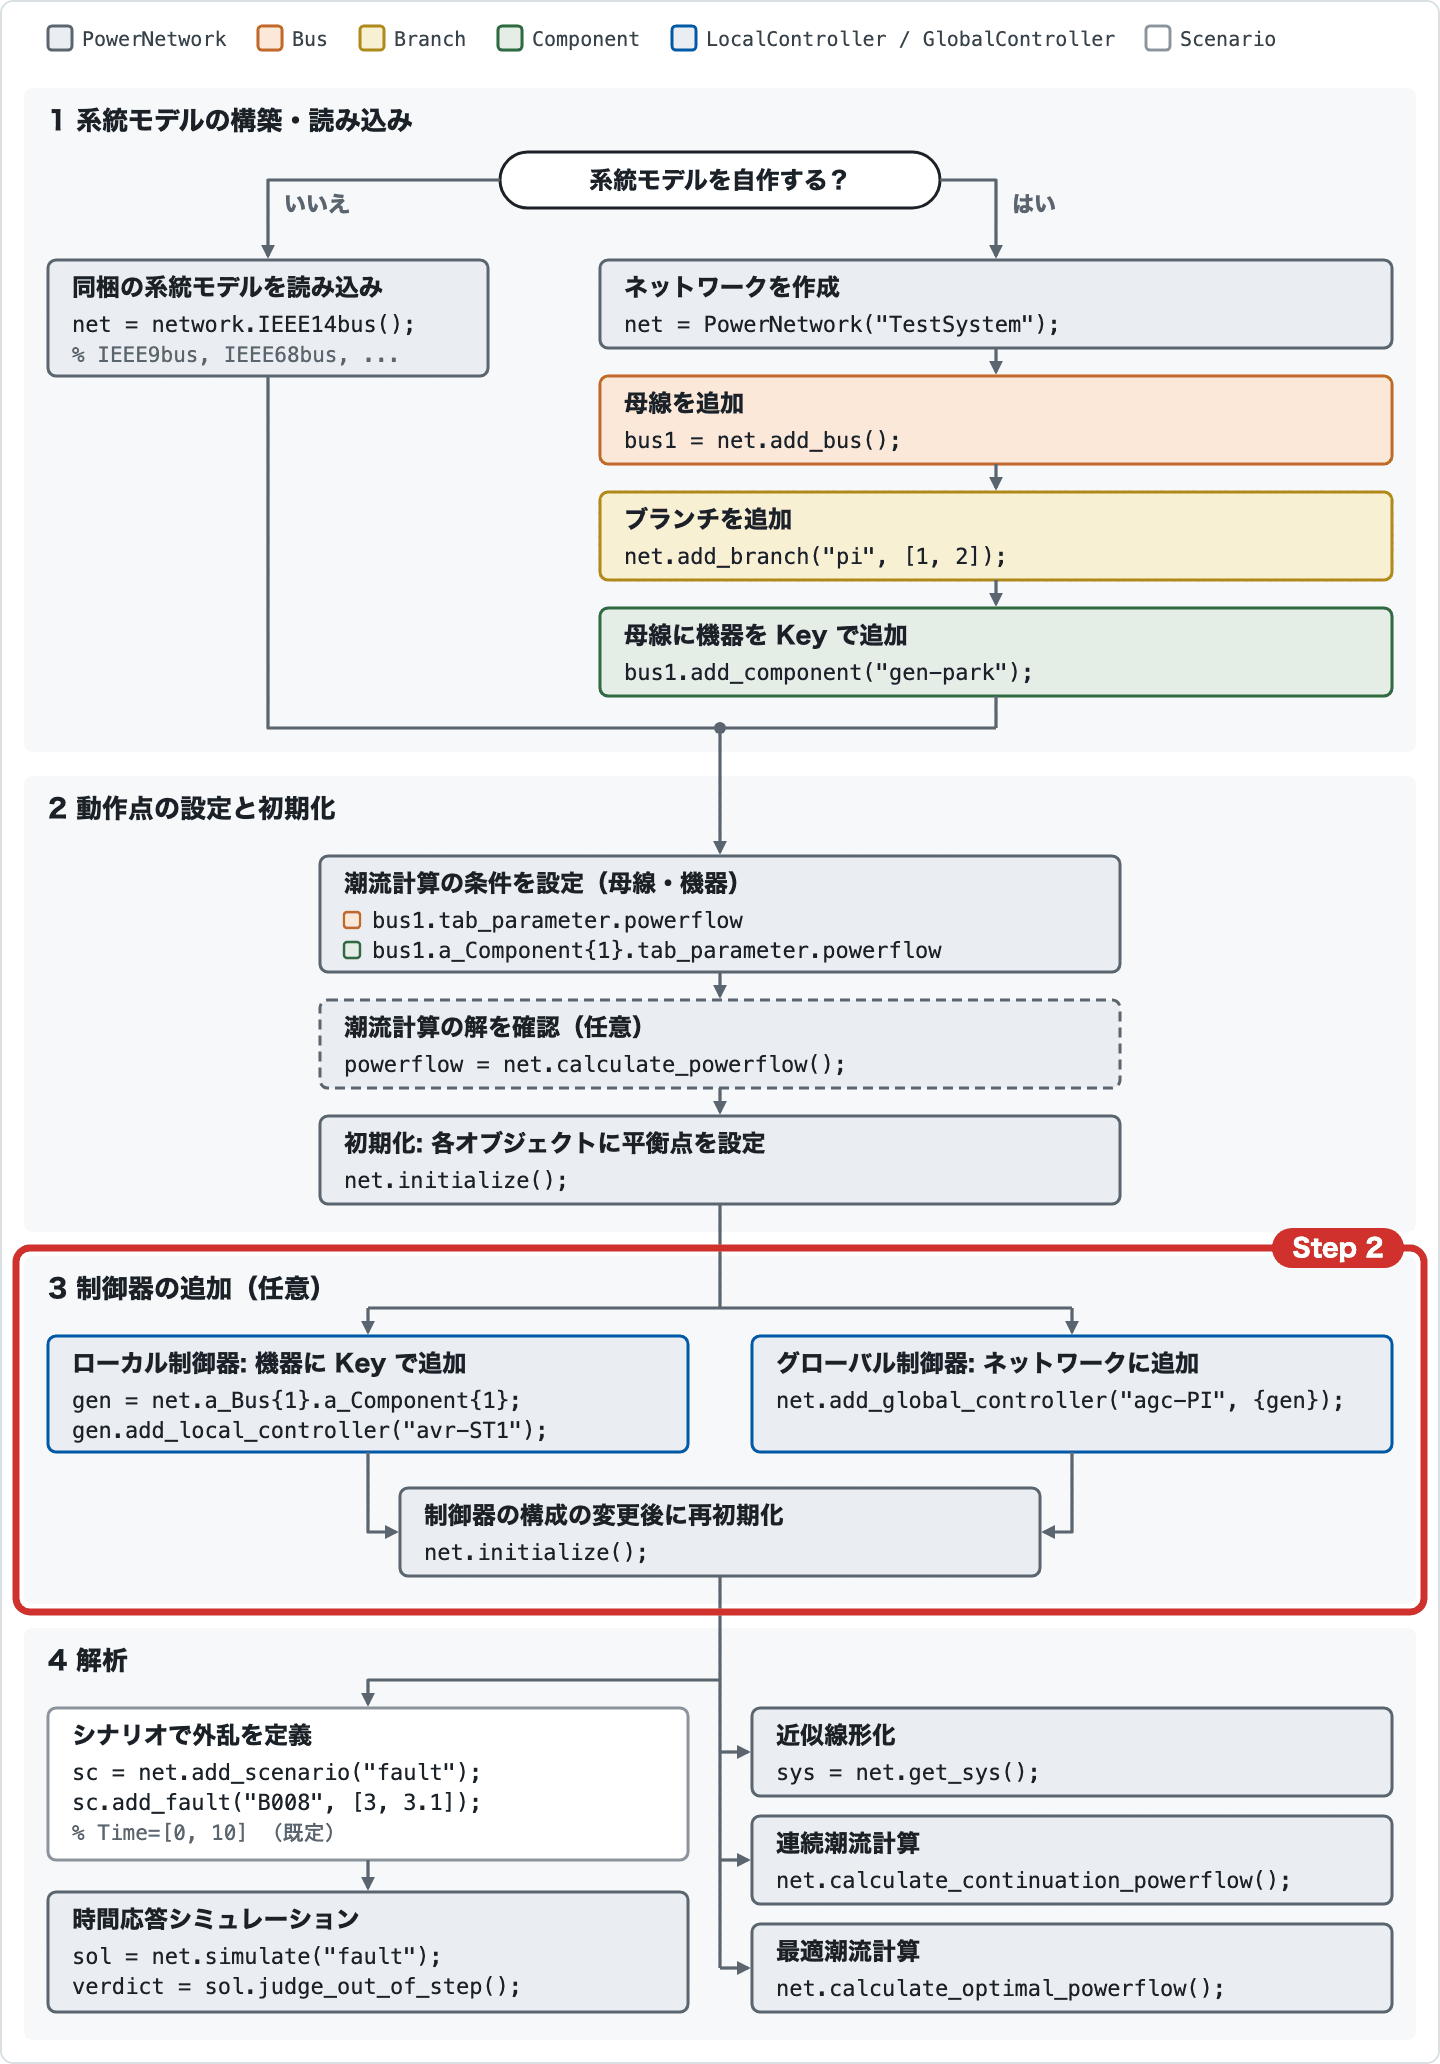

## この Step で分かること

- 制御器の付き方と、ローカル制御器・グローバル制御器の違い

- 種類（Key）を `GUILDA.dictionary` で確かめてから選び、ローカル制御器を付ける・付け替える・取り外す方法（`add_local_controller`・`set_avr`・`set_pss`・`set_governor`・`remove_local_controller`）

- 発電機に付いている制御器の取り出し方（`avr`・`pss`・`governor`）と、信号のつながりの確かめ方（`disp_connection`）

- グローバル制御器（AGC）の付け外し（`add_global_controller`・`remove_global_controller`）

- 付け外しの後に `initialize` が必要な理由と、`initialize` が失敗したときの見方

各節は、制御器を付け外しして解析の準備をするのに要るコードだけで進みます。**確かめる（省略できます）** の下のコードは、中身を見るためのものです。飛ばしても最後まで動きます。

**注意:** GUILDA を起動してから（`>> GUILDA`）実行してください。

## 1. 制御器の付き方

制御器には 2 種類あります。

- ローカル制御器: 1 台の機器に付き、その機器の信号を観測して、その機器の入力を動かします（AVR・PSS・ガバナなど）

- グローバル制御器: 系統に付き、複数の機器をまとめて観測・制御します（AGC）

下の図の上半分が、発電機に付くローカル制御器と信号の向き、下半分が、AGC が各発電機の `omega` を観測して `Pmech` を出す様子です（実線が入力を動かす信号、破線が名前で観測する信号）。図の Key は一例で、この Step では `avr-DC1` なども使います。

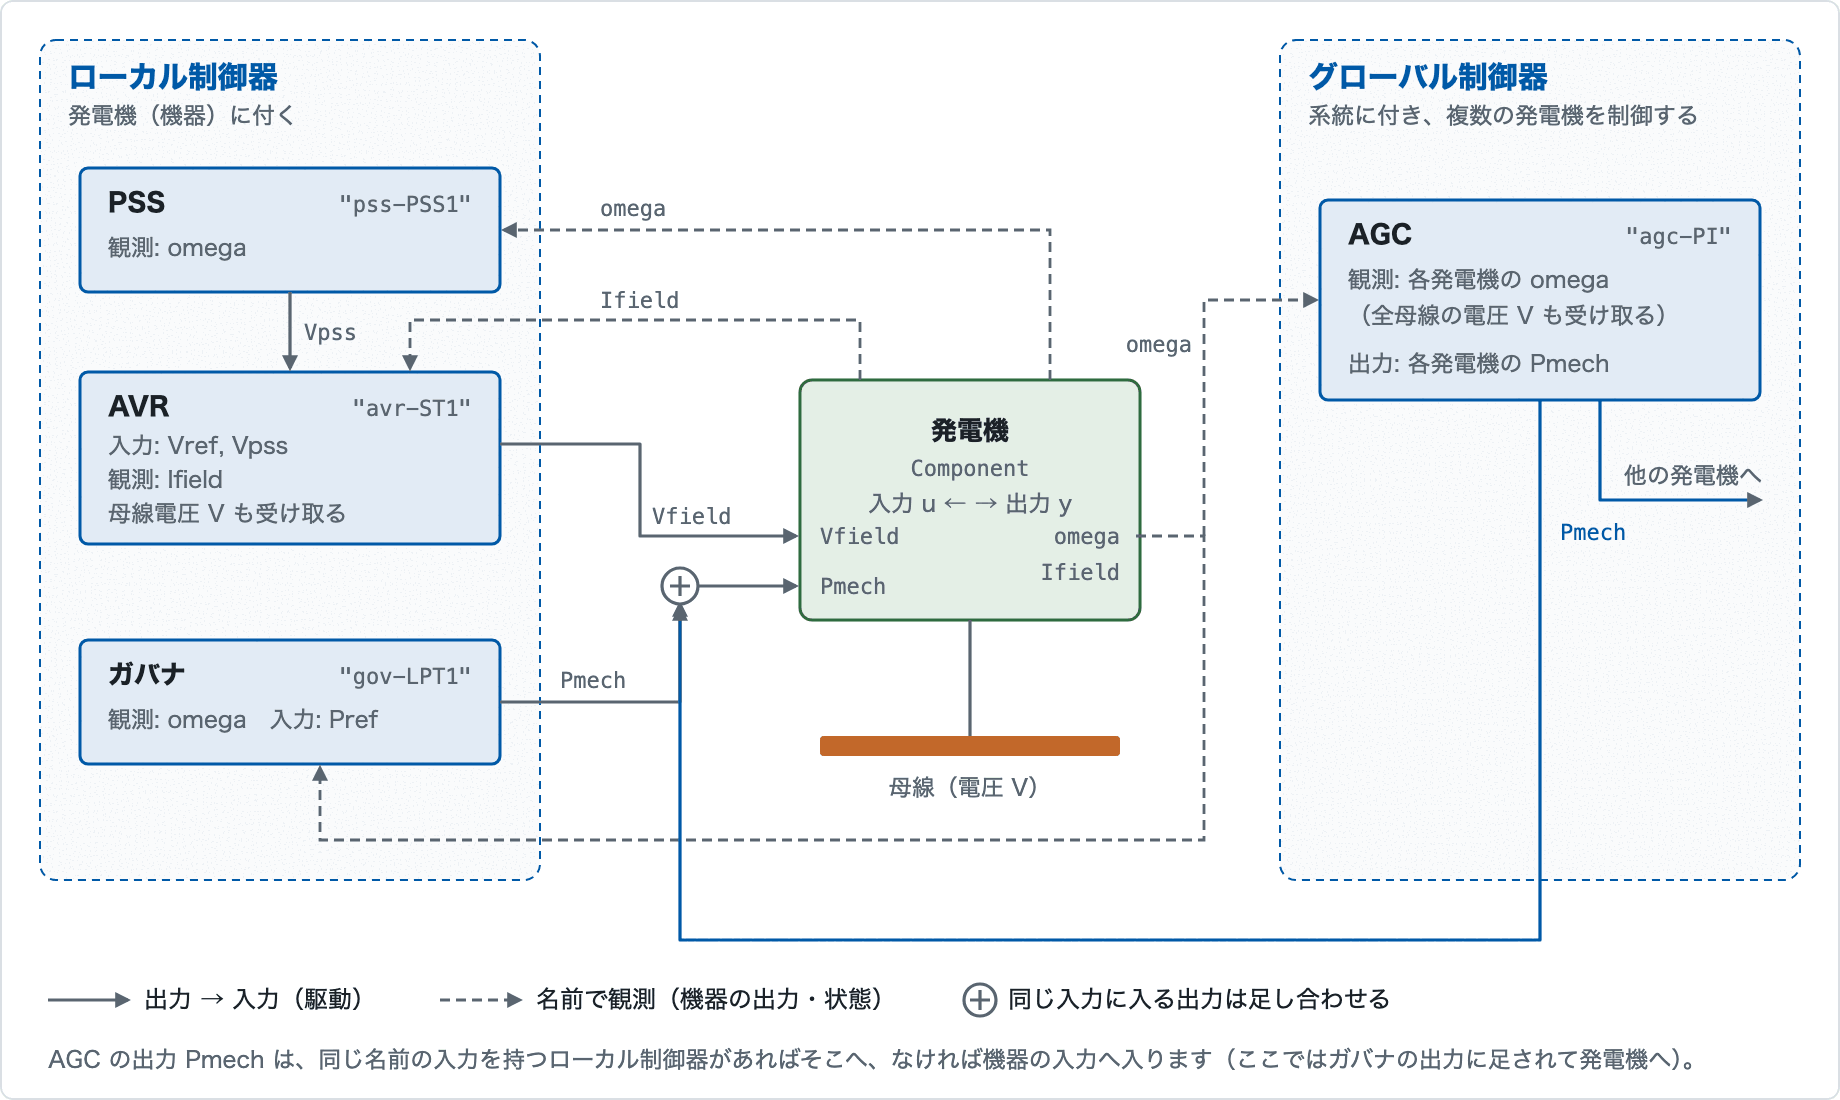

ここからは、同梱の IEEE 9 母線系統を使います。発電機には、読み込むときに AVR・PSS・ガバナが付いています。

net = network.IEEE9bus(LocalController=true);

**確かめる（省略できます）**

同梱の `network.Tutorial10bus` には、GUILDA の制御器のすべての種類が入っています。読み込んで、制御器の付き方を階層で見ます。

n10 = network.Tutorial10bus();

INFO: ' B001 '  set as slack bus.
      P and Q specifications for ' B001SG1 ' ignored in powerflow calculation.
INFO: The global controller 'PowerNetworkAGC1' is connected: Pmech_B001SG1_PowerNetworkAGC1 -> Pmech_B001SG1; Pmech_B002SG1_PowerNetworkAGC1 -> Pmech_B002SG1; Pmech_B003SG1_PowerNetworkAGC1 -> Pmech_B003SG1; Pmech_B004SG1_PowerNetworkAGC1 -> Pmech_B004SG1.


n10.disp_tree();


 PowerNetwork @network.Tutorial10bus
   ┣━━ B001 @Bus
   ┃     ┗━━ B001SG1 @component.generator.park
   ┃          ┣━━ B001SG1CA1 @controller.avr.AVR_DC1
   ┃          ┃     ┗━━ B001SG1CP2 @controller.pss.PSS1
   ┃          ┗━━ B001SG1CG3 @controller.governor.IEEJ_LPT1
   ┣━━ B002 @Bus
   ┃     ┗━━ B002SG1 @component.generator.two_axis
   ┃          ┣━━ B002SG1CA1 @controller.avr.AVR_ST1
   ┃          ┗━━ B002SG1CG2 <a 

AVR（`CA`）の下に PSS（`CP`）が付き、ガバナ（`CG`）は AVR と並びます。母線 3 の発電機には AVR の代わりに LQR（`CL`、`local-LQR`）が付いています。最後の行がグローバル制御器の AGC です。読み込むときの INFO は、`Tutorial10bus` が組み立ての中で Slack 母線と AGC を設定したときの表示です。

## 2. ローカル制御器

ローカル制御器の役割は 4 つあります。

- AVR（`avr-*`）: 端子電圧を観測し、界磁電圧 `Vfield` を動かします（`avr-ST1` は出力の制限のために界磁電流 `Ifield` も観測します）

- PSS（`pss-*`）: 回転の速さ `omega` を観測し、AVR の入力 `Vpss` を動かします。AVR の下に付きます

- ガバナ（`gov-*`）: `omega` を観測し、機械入力 `Pmech` を動かします

- AVR の代わりの制御器（`local-LQR`）: 状態をまとめて観測し、複数の入力を動かします

### 2.1 発電機を取り出す

制御器は機器に付けるので、まず機器を取り出します。`get_element` にタグを渡して、母線 1 の発電機を取り出します。

gen1 = net.get_element("B001SG1");

発電機には、付いている AVR・PSS・ガバナを取り出す `avr`・`pss`・`governor` があります。

**確かめる（省略できます）**

AVR のタグを表示し、続けて `get_element_table` の `Owner` で、その発電機の制御器を一覧します。

gen1.avr.s_tag

ans = "B001SG1CA1"

tab_con = net.get_element_table(Owner="B001SG1");
tab_con(:, ["Role","Key","Class","Parent"])

ans = 3×4 table
                     Role           Key                    Class                   Parent   
                  __________    ____________    ____________________________    ____________

    B001SG1CA1    "avr"         "avr-ST1"       "controller.avr.AVR_ST1"        "B001SG1"   
    B001SG1CP2    "pss"         "pss-PSS1"      "controller.pss.PSS1"           "B001SG1CA1"
    B001SG1CG1    "governor"    "gov-static"    "controller.governor.Static"    "B001SG1"   


同期発電機には、つくったときから `avr-static` と `gov-static`（界磁電圧と機械入力を平衡点の値のまま保つだけの制御器）が付いていて、ほかの AVR やガバナを付けると置き換わります。IEEE 9 母線系統の発電機では、AVR が `avr-ST1` に置き換わってその下に PSS（`pss-PSS1`）が付き、ガバナは `gov-static` のままです。

**注意:** 機器の `a_LocalController` にも同じ制御器が入っています（AVR、ガバナの順。PSS は AVR の `a_LocalController`。表の `Parent` が親）。負荷など発電機でない機器には `avr`・`pss`・`governor` がないので、`a_LocalController` から取り出します。

### 2.2 制御器を付ける・付け替える

まずローカル制御器の種類を確かめてみましょう。

GUILDA.dictionary("LocalController");

 
Search for 'LocalController' class
  Link   Type        Key           class tree
  [doc]  -:Abstract                LocalController
  [doc]  o:Concrete  avr-static      ┣━━ controller.avr.Static
  [doc]  -:Abstract                  ┣━━ controller.avr.abstract
  [doc]  o:Concrete  avr-DC1         ┃   ┣━━ controller.avr.AVR_DC1
  [doc]  o:Concrete  avr-ST1         ┃   ┗━━ <a href=

役割（AVR・PSS・ガバナ・LQR）ごとに、Key が並びます。`[doc]` をクリックすると、そのクラスの説明のページが開きます。今回は、AVR に `avr-DC1` を、ガバナに `gov-LPT1` を使います。

`add_local_controller` で、Key を指定して制御器を付けます。

gen1.add_local_controller("avr-DC1", parameter=struct(kap=50));

gen1.add_local_controller("gov-LPT1", parameter=struct(Prate=2));

新しい AVR は前の AVR と置き換わり（警告で示されます）、前の AVR に付いていた PSS は新しい AVR の下に移ります。ガバナは `gov-static` と置き換わります。

ここで使うオプションは `parameter` で、パラメータを既定値から変えるときに構造体で渡します。省略したパラメータはクラスの既定値になります。`gov-LPT1` の `Prate` は定格出力（系統の基準電力についての値）で、小さすぎると平衡点の出力が出せず `initialize` がエラーになります（4 節）。その他のオプションは、`add_local_controller` のリファレンスで確かめられます: [その他のオプションはこちら](matlab:writelines("<script>location.replace('file://"+replace(fullfile(GUILDA.pwd,"_GUILDAdoc","method.html"),filesep,"/")+"#class=Component&method=add_local_controller')</script>",fullfile(tempdir,"guilda_doc.html"));web(fullfile(tempdir,"guilda_doc.html"),"-browser"))（ブラウザで開きます）

発電機には、役割を確かめてから付ける `set_avr`・`set_pss`・`set_governor` もあります。中身は `add_local_controller` と同じで、役割の違う Key を渡すとエラーになります。PSS を付け直します。

gen1.set_pss("pss-PSS1", parameter=struct(kpss=0.5));

**確かめる（省略できます）**

付いている制御器と、AVR のパラメータを見ます。

gen1.disp_tree();


 B001SG1 @component.generator.one_axis
   ┣━━ B001SG1CA3 @controller.avr.AVR_DC1
   ┃     ┗━━ B001SG1CP5 @controller.pss.PSS1
   ┗━━ B001SG1CG4 @controller.governor.IEEJ_LPT1




gen1.avr.tab_parameter.dynamics

ans = 1×14 table
    ttr     Vap_max    Vap_min    kap    tap    aex1     aex2      tex      bex      kst     tst     Vfld_max    Vfld_min    Limiter
    ____    _______    _______    ___    ___    ____    ______    _____    _____    _____    ____    ________    ________    _______

    0.01      Inf       -Inf      50     0.2     1      0.0039    0.314    1.555    0.063    0.35      Inf         -Inf       true  


gen1.pss.s_tag

ans = "B001SG1CP5"

`kap` が 50 になり、ほかのパラメータは既定値です。制御器のタグは、機器のタグ・役割の記号（`CA` は AVR、`CP` は PSS、`CG` はガバナ、`CL` は LQR）・番号です。番号は機器の制御器の通し番号なので、付け替えると増えていきます。

### 2.3 制御器を取り外す

`remove_local_controller` で、タグを指定して取り外します。PSS だけを外し、続けて AVR を外します。

gen1.remove_local_controller(gen1.pss.s_tag);
gen1.remove_local_controller(gen1.avr.s_tag);

AVR を外すと、界磁電圧は平衡点の値のままになります（`avr-static` は戻りません）。

**注意:** PSS が付いたままの AVR を外すと、エラーになります。PSS ごと外すには `RemoveNested=true` を指定します（例: `gen.remove_local_controller(gen.avr.s_tag, RemoveNested=true)`）。取り外した制御器のオブジェクトは削除され、使えなくなります。

**確かめる（省略できます）**

gen1.disp_tree();


 B001SG1 @component.generator.one_axis
   ┗━━ B001SG1CG4 @controller.governor.IEEJ_LPT1




### 2.4 信号のつながりを確かめる

制御器は、名前の同じ信号どうしでつながります。制御器の入力 `sv_u` は機器の出力や状態を観測し、出力 `sv_y` は機器の入力を動かします。1 節の図のとおりです。この節のコードは、つながりを見るだけのものです。

**確かめる（省略できます）**

母線 2 の発電機と制御器の入力と出力を、`get_element_table` の `Owner` に母線のタグを渡して見ます。

tab_b2 = net.get_element_table(Owner="B002");
tab_b2(:, ["Role","Input","Output"])

ans = 4×3 table
                     Role              Input                Output     
                  __________    ____________________    _______________

    B002SG1       ""            "Pmech, Vfield"         "omega, Ifield"
    B002SG1CA1    "avr"         "Vref, Vpss, Ifield"    "Vfield"       
    B002SG1CP2    "pss"         "omega"                 "Vpss"         
    B002SG1CG1    "governor"    "Pmech_ref"             "Pmech"        


つながりは `disp_connection` で確かめられます。`Owner` で、その機器とその制御器に絞ります。

net.disp_connection(Owner="B002SG1");


 Signal connections of PowerNetwork @network.IEEE9bus
 <: input port, o: held object; several sources are summed (━┳); Kind: local, global, observe
 Bus voltages that controllers read directly are not connections and are not listed.

 B002 @Bus
   ┗━━o B002SG1 @component.generator.one_axis
         ┣━━< Pmech  ━━ output Pmech of B002SG1CG1   [local]
         ┣━━< Vfield ━━ output Vfield of B002SG1CA1  [local]
         ┗━━o B002SG1CA1 @controller.avr.AVR_ST1
               ┣━━< Vpss   ━━ output Vpss of B002SG1CP2  [local]
               ┣━━< Ifield ━━ output Ifield of B002SG1   [observe]
               ┗━━o B002SG1CP2 @controller.pss.PSS1
                     ┗━━< omega ━━ outpu

`<` が入力です。`[observe]` は制御器が機器の出力を観測するつながりで、PSS の入力 `omega` が発電機の出力 `omega` を観測しています。制御器の出力が親の入力を動かすつながりは `[local]` で示されます。AVR が読む端子電圧は母線から直接読むので、つながりには表れません。

**注意:** `disp_connection(Kind=["local","global","observe","equilibrium"])` で、何もつながらず平衡点の値のままの入力（`equilibrium`）も表示します。同じつながりを表で得るには `get_variable_map` の 4 番目の出力を使います（Step 3）。AVR の代わりに `local-LQR` を、AVR の下に PSS の代わりに `pss-retrofit` を付けることもできます。どちらも `initialize` のときに系統の線形モデルから設計されます（Part 8）。

## 3. グローバル制御器

グローバル制御器は、複数の機器をまとめて観測・制御する制御器です。1 節の図の下半分が、AGC が各発電機の `omega` を観測し、`Pmech` を出す様子です。

### 3.1 グローバル制御器を付ける

まずグローバル制御器の種類を確かめてみましょう。

GUILDA.dictionary("GlobalController");

 
Search for 'GlobalController' class
  Link   Type        Key     class tree
  [doc]  -:Abstract          GlobalController
  [doc]  o:Concrete  agc-PI    ┗━━ controller.agc.broadcast_PI_AGC


今回は、AGC の `agc-PI` を使います。`add_global_controller` に、Key と制御する機器（タグまたはオブジェクト）を渡します。母線 1・2 の発電機を制御する AGC を付けます。

agc = net.add_global_controller("agc-PI", ["B001SG1","B002SG1"], parameter=struct(kP=10, kI=50));

INFO: The global controller 'PowerNetworkAGC1' is connected: Pmech_B001SG1_PowerNetworkAGC1 -> Pmech_B001SG1; Pmech_B002SG1_PowerNetworkAGC1 -> Pmech_B002SG1.


INFO の表示が、AGC の出力がどの入力を動かすかを示します。AGC は 2 台の発電機の `omega` を観測し、`Pmech` を動かします。AGC の出力は、ガバナの出力と足し合わされて発電機の入力 `Pmech` に加わります。

ここで使うオプションは `parameter`（パラメータを構造体で渡す）です。その他のオプションは、`add_global_controller` のリファレンスで確かめられます: [その他のオプションはこちら](matlab:writelines("<script>location.replace('file://"+replace(fullfile(GUILDA.pwd,"_GUILDAdoc","method.html"),filesep,"/")+"#class=PowerNetwork&method=add_global_controller')</script>",fullfile(tempdir,"guilda_doc.html"));web(fullfile(tempdir,"guilda_doc.html"),"-browser"))（ブラウザで開きます）

**注意:** タグは系統のタグ・`AGC`・番号です（同梱の系統のタグは `"PowerNetwork"` です）。グローバル制御器は `net.a_GlobalController` に入っています。制御する機器は、グローバル制御器を取り外すまで置き換えたり取り外したりできません。

**確かめる（省略できます）**

タグとパラメータ、つながりを見ます。`tab_parameter` の表の行は、制御する機器ごとのパラメータです。

agc.s_tag

ans = "PowerNetworkAGC1"

agc.tab_parameter

ans = 2×1 table
                  dynamics              
    ____________________________________

               alpha    beta    kP    kI
               _____    ____    __    __
                                        
    B001SG1      1       1      10    50
    B002SG1      1       1      10    50


net.disp_connection(Kind="global");


 Signal connections of PowerNetwork @network.IEEE9bus
 <: input port, o: held object; several sources are summed (━┳); Kind: global
 Bus voltages that controllers read directly are not connections and are not listed.

 B001 @Bus
   ┗━━o B001SG1 @component.generator.one_axis
         ┗━━< Pmech ━━ output Pmech of PowerNetworkAGC1  [global]

 B002 @Bus
   ┗━━o B002SG1 @component.generator.one_axis
         ┗━━< Pmech ━━ output Pmech of PowerNetworkAGC1  [global]

 Not shown (option Kind): 7 local, 7 observe, 13 equilibrium connections



制御している機器を置き換えようとすると、エラーになります。

try
    net.a_Bus{2}.replace_component("B002SG1", "gen-1axis");
catch ME
    disp(ME.message)
end

The component 'B002SG1' is controlled by the global controller 'PowerNetworkAGC1'.
Remove the global controller first with net.remove_global_controller(TAG).


### 3.2 グローバル制御器を取り外す

`remove_global_controller` で、タグを指定して取り外します。

net.remove_global_controller(agc.s_tag);

**確かめる（省略できます）**

numel(net.a_GlobalController)

ans = 0

## 4. 付け外しと initialize

制御器を付け外しすると、系統の平衡点は古くなります。時間シミュレーションや近似線形化の前に、`initialize` で平衡点を求め直します。

[~, flag] = net.initialize();
flag

flag = 1

`flag` が 1 なら成功です。`initialize` は、潮流計算の解から機器の平衡点を求め、制御器の平衡点（制御器の出力が機器の入力の平衡点の値になる点）を求めます。`local-LQR` などはここで設計されます。

平衡点を求められないと、`initialize` はエラーで理由を示します。例として、母線 2 の発電機（出力 1.63 pu）に、定格出力 `Prate` が 1 pu のガバナを付けます。

g2 = net.get_element("B002SG1");
g2.set_governor("gov-LPT1", parameter=struct(Prate=1));
try
    net.initialize();
catch ME
    disp(ME.message)
end

IEEJ_LPT1 'B002SG1CG3': the turbine output 1.63 pu of the rated MW (Pmech / Prate, Prate = 1) required at the equilibrium needs the servo position 1.63 pu, which is not within the limits [0, 1.05] pu. Check Prate (the rated MW of the machine divided by the system base; NaN uses the operation Pmax of the generator), widen pos_min and pos_max, or change the operating point of the generator.


メッセージが、どの制御器のどの値が範囲を外れたかと、直し方を示します。`Prate` を直して求め直します。

g2.governor.tab_parameter.dynamics.Prate = 2;
[~, flag] = net.initialize();
flag

flag = 1

**注意:** 制御器のパラメータを `tab_parameter` で書き換えた後も、`initialize` が必要です（パラメータの読み書きは Step 3）。同梱の系統は読み込むときに `initialize` まで済んでいます。

## まとめ

- 制御器には、1 台の機器に付くローカル制御器と、系統に付いて複数の機器を制御するグローバル制御器があります。種類は `GUILDA.dictionary("LocalController")`・`GUILDA.dictionary("GlobalController")` で確かめてから、Key で選びます。

- ローカル制御器は `add_local_controller`（発電機では `set_avr`・`set_pss`・`set_governor` も）で付け、`remove_local_controller` で外します。発電機の制御器は `avr`・`pss`・`governor` で取り出し、つながりは `disp_connection` で確かめます。

- グローバル制御器は `add_global_controller`・`remove_global_controller` で付け外しします。

- 付け外しの後は、解析の前に `initialize` で平衡点を求め直します。

## 次の Step と関係する Part

- 次の Step 3（系統データの見方と編集）では、母線・ブランチ・機器・制御器のデータを取り出し、パラメータを読み書きする方法を扱います。

- 制御器の考え方は Part 1（電力系統の作成と機器の種類）で、制御器の設計は Part 8（制御器の設計と自作）で説明しています: [講義ノート Part 1](matlab:web("https://guilda-dev.github.io/guilda-doc/lecture/part1-network-components.html","-browser"))・[講義ノート Part 8](matlab:web("https://guilda-dev.github.io/guilda-doc/lecture/part8-controller-design.html","-browser"))（ブラウザで開きます）

[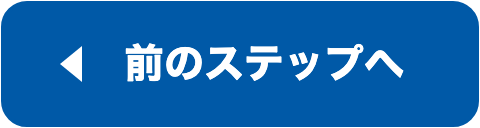](matlab:open('Step1_BuildNetwork.mlx'))　　[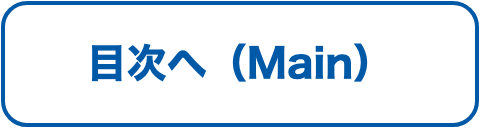](matlab:open('Main.mlx'))　　[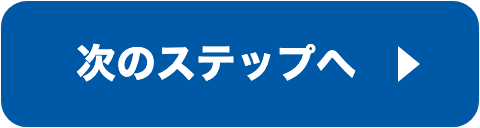](matlab:open('Step3_NetworkData.mlx'))